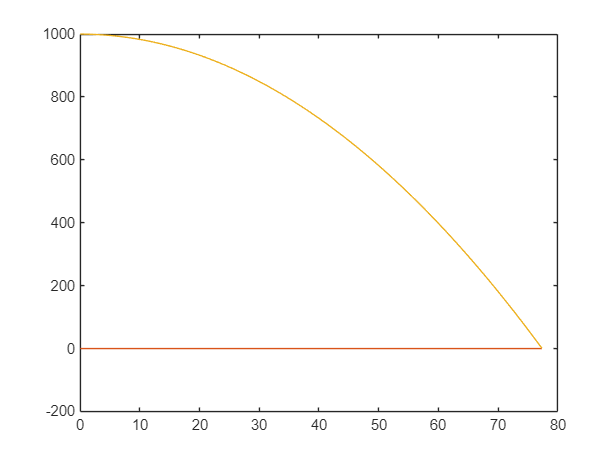

clc
clear
close all

load("sim.mat")

figure()
plot(out.main_clock, out.vehicle_position)

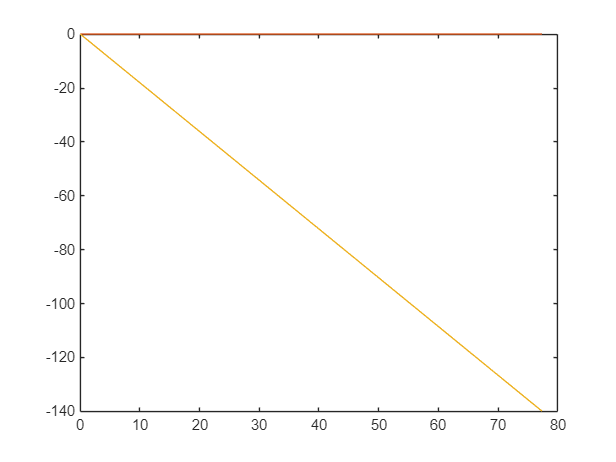


figure()
plot(out.main_clock, out.vehicle_velocity)

figure()

result = 5.4093e+03

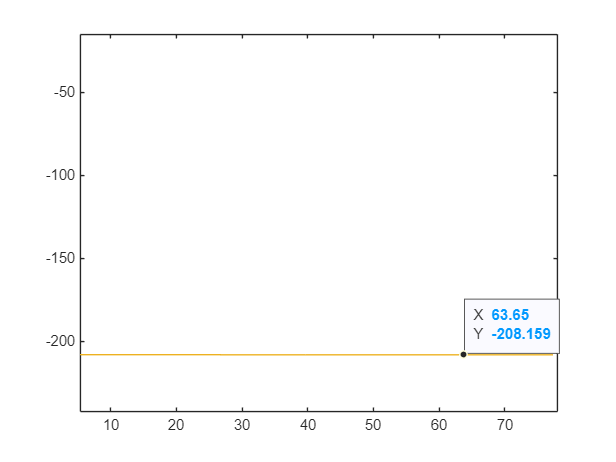

plot(out.main_clock, out.F_gravity)


$$y=y_0 +v_o t+\frac{1}{\;2}{\mathrm{at}}^2$$


$y_0 =h=1000$ e $a=g=9\ldotp 81$


$$t=\sqrt{\;\frac{2h}{g\;}}\Longrightarrow t=\sqrt{\;\frac{2\times 1000}{9\ldotp 81}}=14\ldotp 28\;s$$



[result, ~, ~] = trapezoidal_integration(out.main_clock, -out.vehicle_velocity(:, 3))